# Getting Started with mexopencv

## Features

The package already contains over 450 OpenCV functions/classes (covering many `opencv` and `opencv_contrib`modules). You can check a list of supported functions in the user documentation.

If you can't find your favorite one, you can easily add a new Mex function through `MxArray` class. MxArray is a data conversion utility for MATLAB's native array and OpenCV data types.

With this class, your MEX-function is as simple as the following:

## Examples

Here is an example of how simple it is to use an OpenCV function from MATLAB to detect faces:

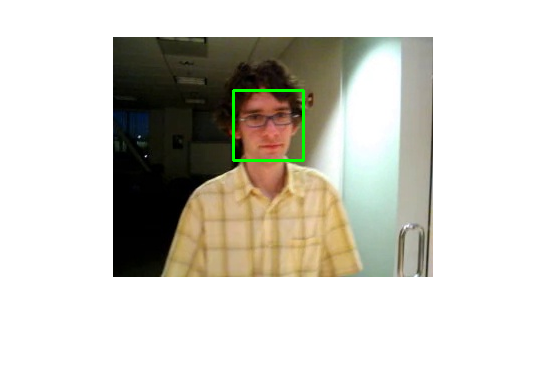

% Load a face detector and an image
cascade = cv.CascadeClassifier(fullfile(mexopencv.root, 'opencv', 'etc', 'haarcascades', 'haarcascade_frontalface_alt.xml'));
im = imread(fullfile(mexopencv.root, 'test', 'facemark','david1.jpg'));

% Preprocess image
gr = cv.cvtColor(im, 'RGB2GRAY');
gr = cv.equalizeHist(gr);

% Detect faces
boxes = cascade.detect(gr, ...
    'ScaleFactor',1.3, 'MinNeighbors',2, 'MinSize',[30 30]);

% Draw results
for i = 1:numel(boxes)
    im = cv.rectangle(im, boxes{i}, 'Color',[0 255 0], 'Thickness',2);
end
imshow(im);

Would you like to use a camera input? No problem.

% Connect to a camera
camera = cv.VideoCapture();
pause(2);
for i = 1:50
    % Capture and show frame
    frame = camera.read();
    imshow(frame);
    drawnow;
end
camera.release();

Interested in deep learning, here is an example of image identification using a pretrained convolutional neural network:

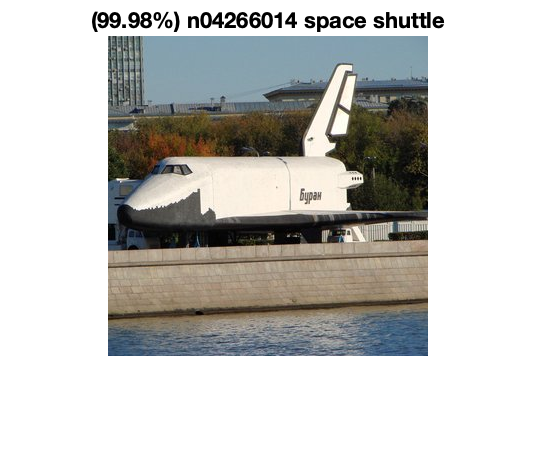

% load pretrained model, along with list of 1000 recognized categories
dname = fullfile(mexopencv.root(), 'test', 'dnn', 'GoogLeNet');
net = cv.Net('Caffe', ...
    fullfile(dname, 'deploy.prototxt'), ...
    fullfile(dname, 'bvlc_googlenet.caffemodel'));
labels = fileread(fullfile(dname, 'synset_words.txt'));
labels = regexp(strtrim(labels), '\n', 'split');

img = imread(fullfile(mexopencv.root, 'test', 'space_shuttle.jpg'));
imshow(img)
net.setInput(cv.Net.blobFromImages(img, 'Size',[224 224], 'SwapRB',true));
prob = net.forward();
[~,idx] = max(prob);
title(sprintf('(%.2f%%) %s', prob(idx)*100, labels{idx}))

The same using the webcam as input: 

% load pretrained model, along with list of 1000 recognized categories
dname = fullfile(mexopencv.root(), 'test', 'dnn', 'GoogLeNet');
net = cv.Net('Caffe', ...
    fullfile(dname, 'deploy.prototxt'), ...
    fullfile(dname, 'bvlc_googlenet.caffemodel'));
labels = fileread(fullfile(dname, 'synset_words.txt'));
labels = regexp(strtrim(labels), '\n', 'split');

% open webcam
cap = cv.VideoCapture(0);
hImg = imshow(cap.read());
set(gcf,'Visible','on')
while ishghandle(hImg)
    % read frame and classify image
    img = cap.read();
    net.setInput(cv.Net.blobFromImages(img, 'Size',[224 224], 'SwapRB',true));
    prob = net.forward();
    [~,idx] = max(prob);

    % show prediction
    set(hImg, 'CData',img)
    title(sprintf('(%.2f%%) %s', prob(idx)*100, labels{idx}))
    drawnow
end

cap.release();

Check out the included samples for more demos

## Notes

### Deep learning files

Deep learning network definitions (dnn) are not included in this toolbox, but are in a separate file, dnn.zip. To install them:

mexopencv.install_dnn('dnn.zip')

Their location is in:

fullfile(mexopencv.root, 'test', 'dnn')